TSL control

clear; 
% Laser
dllPath = fullfile(pwd, 'Santec_FTDI.dll');
asmInfo = NET.addAssembly(dllPath); pause(1);

TSL = Santec_FTDI.FTD2xx_helper('20060036');
pause(1);
TSL.Query('*IDN?')

ans = SANTEC, TSL-550,20060036,0003.0050


% connect to agilent 8164B
delete(instrfindall);
agi = start_laser(); % note: this is a legacy function name for the 8164b

Agilent Technologies,8164B,DE48202184,V5.24(71730)



 % Turn on laser
TSL.Query('LO')

 % Turn off laser
TSL.Query('LF')

ans = 0000.0050


 % Shutter on
TSL.Query('SC')

 % Shutter off
TSL.Query('SO')

 % Set wavelength
temp_wav = 1551

temp_wav = 1551

TSL.Query(strcat('WA',num2str(temp_wav,'%.4f'))); pause(0.05)
clear('temp_wav')

 % Set power
temp_pwr = 3

temp_pwr = 3

TSL.Query(strcat('LP',num2str(temp_pwr,'%.2f'))); pause(0.05)
clear('temp_pwr')

% Laser Power in mW
TSL.Query('LP')

ans = 005.008


temp_wvStart = 1540

temp_wvStart = 1540

temp_wvEnd = 1550

temp_wvEnd = 1550

temp_wvRes = 0.002

temp_wvRes = 0.0020

santec_wvRes = 0.005

santec_wvRes = 0.0050

agi_wvRes = 0.001

agi_wvRes = 1.0000e-03

temp_wvSpeed = 10

temp_wvSpeed = 10

 
% Scan script settings
% TSL settings
TSL.Write('*CLS'); pause(0.1)
TSL.Write('*RST'); pause(0.1)
TSL.Query('SM 1'); % Sweep Mode; 1-continous one way, 2-continous two ways, 3- step one way
pause(0.1); TSL.Query('SZ 1'); % Number of sweeps
pause(0.1); TSL.Query('TM 3'); % Trigger behaviour; 1-Start, 2-Stop, 3-Step
pause(0.1); TSL.Query(char(sprintf('SS %.4f', temp_wvStart))); % Start wavelength (nm)
pause(0.1); TSL.Query(sprintf('SE %.4f', temp_wvEnd));
%pause(0.1); TSL.Query('SA 0'); % Time between sweeps (s)
%pause(0.1); TSL.Query('SB 0.1'); % Step time (s)
%pause(0.1); TSL.Query('WW 0.1'); % Step interval (nm)
pause(0.1); TSL.Query(sprintf('SN %.1f',temp_wvSpeed)); % Continous sweep speed (nm/s); [0.5:0.1:100]
pause(0.1); TSL.Query(sprintf('TW %.4f',santec_wvRes)); %0.0015 Trigger step (nm); [0.0001:0.0001:160] <1kHz
%TSL.Query("WA"+num2str(temp_wvStart,'%.4f')); pause(0.3)
wvs = temp_wvStart:agi_wvRes:temp_wvEnd;
scanTime = ceil((temp_wvEnd-temp_wvStart)/temp_wvSpeed)

scanTime = 1


% agilent setup
agilent_detector_range = 0; % dBm, multiple of 10 from -60 to 10
agilent_num_points = length(wvs);
agilent_sample_period = agi_wvRes/temp_wvSpeed

agilent_sample_period = 1.0000e-04

%temp_wvRes/temp_wvSpeed
% closed loop triggering from every santec trigger
% agilent_setup_for_santec(agi, agilent_num_points, agilent_detector_range);
% open loop triggering only from first santec trigger
agilent_setup_logging(agi, agilent_num_points, agilent_sample_period);
clear('temp_wvEnd','temp_wvStart','temp_wvSpeed','temp_wvRes')



TSL.Query('SG')

ans = 0000.0100


max_wait_time = scanTime+5; % time to wait for agilent before timing out
laser.Timeout = max_wait_time;
loggingSuccessful = agilent_wait_for_logging(agi, max_wait_time);

Agilent power meter logging in progress...
Agilent complete!


if(loggingSuccessful)
    [channel1, channel2] = agilent_get_logging_result(agi);
    agilent_reset_triggers(agi);
else
    warning("Logging did not finish in alloted time.");
end

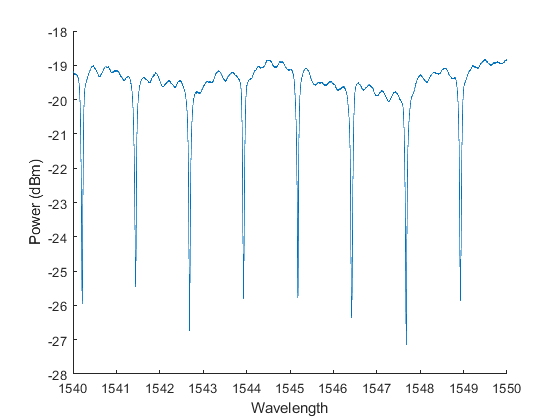

figure; hold on;
plot(wvs, 10*log10(abs(channel1)) + 30);
%plot(wvs, 10*log10(abs(channel2)) + 30);
hold off;
xlabel("Wavelength");
ylabel("Power (dBm)");

% save result
[output_filename, output_path] = uiputfile('*', 'Select location to save data:');
if(output_filename)
    %save(strcat(output_path,output_filename), 'wvs', 'channel1', 'channel2');
    save(strcat(output_path,output_filename), 'wvs', 'channel1');
else
    disp("File save cancelled");
end

File save cancelled


 % Disconnect
 
% if(exist('TSL','var'))
%     TSL.CloseUsbConnection(); % Laser
%     clear('TSL')
% end